# Plotting the US election map with adjustable color scaling

The query of how to do this came from BlueSky [Jerb ⚒️🇵🇸🧬: "i might be teaching stats again this coming spring as an adjunct. does anyone know of a resource to plot the US election map but with adjustable color scaling? i start off each semester on DataViz R would be ideal, MATLAB too, could pick up some other platform if needed" — Bluesky](https://bsky.app/profile/jerbivore.bsky.social/post/3larei7t4ps2g)

Here's how to do it (courtesy of Adam Danz of MathWorks).  It assigns colors red, blue and purple at random

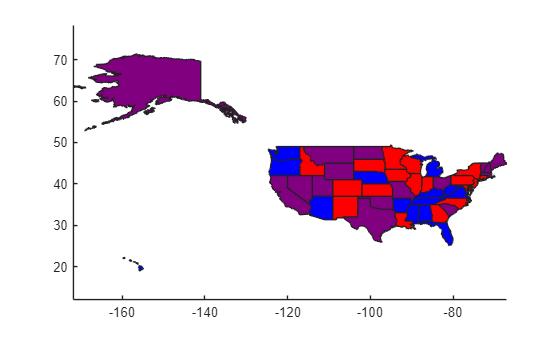

figurestates = readgeotable("usastatelo.shp");
states.ElectionResults = randi(3,height(states),1); 
redBluePurple = [1 0 0; 0 0 1; .5 0 .5];
h = height(states);
faceColors = makesymbolspec("Polygon",    {'INDEX',[1 h],'FaceColor',redBluePurple(states.ElectionResults,:)});
geoshow(states,"DisplayType","polygon","SymbolSpec",faceColors)
axis equal